# **IS501 NMTB HELMHOLTZ** **MAGNETIC TEST BED SIMULATION**

The University of Beihang conducted an extensive investigation for the design and construction of the magnetic testbed denominated IS501NMTB. According to [1], the primary objective of this testbed is to accurately reproduce Earth’s magnetic field along the satellites’ orbits and the prediction of Earth’s magnetic field throughout the orbit with the utilization of Helmholtz coils.

## 1.Helmholtz Coils (HC)

### 1.1. Magnetic Model on the spin axis

A pair of Square Helmholtz coils were used to generate a uniform magnetic field. In [1-3] it is explained that Helmholtz coils are constructed under the Biot-Savart law which is described as follows.

$\vec{B} = \frac{N \mu_0}{4\pi} \int \frac{I\vec{dL}\times\hat{r}}{r^2}$   (1.1)

Where:

$\vec{B}$ : Is the magnetic flux density (Tesla).

$\vec{dL}$: Is the differential of length in the direction of L (meter).

$r$: is the distance from the differential element to the point to be studied (meter).

$\hat{r}$: is the vector unit in vector direction $\hat{r}$.

$\mu_0$: Is the constant of magnetic permeability in vacuum with $\mu_0 = 4\pi E-7$(Tm/A).

$I$: is the intensity of the electric current in the conductor (Ampere).

$N$: Is the number of turns in the coil.

In our case, according to [1, 4] and [6] the Biot-Savart Law solution for one coil pairs that generates a magnetic flux evaluated in the $Z$ direction (Figure 1 ) is denoted by:

$\vec{B}(z) = \frac{2\mu_0 NIa^2}{\pi} \times \left[\frac{1}{\left(a^2+\left(z+\frac{h}{2}\right)^2\right) \left(2a^2+\left(z+\frac{h}{2}\right) ^2 \right)^{1/2}} + \frac{1}{\left(a^2+\left(z-\frac{h}{2}\right)^2\right) \left(2a^2+\left(z-\frac{h}{2}\right) ^2 \right)^{1/2}}\right] \hat{z}$  (1.2)

Where:

- L = Coil side lenght

- a = L/2

- h = distance between coils

- z = distance of evaluation from the separation center.

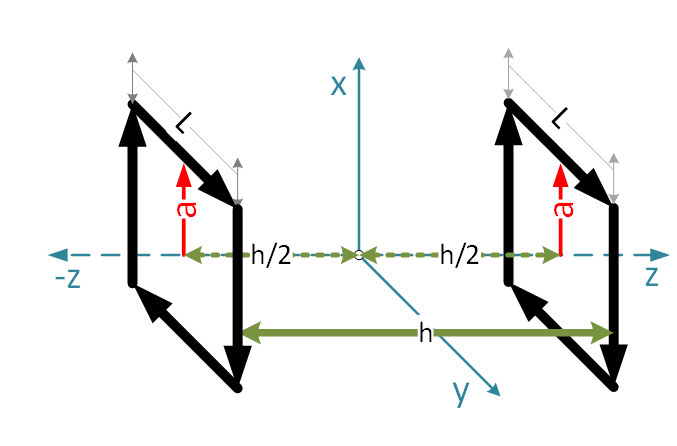

According to [1] the magnetic field in the $z=0$ is predicted by equation (1.3)

$\vec{B(0)} = \frac{4\mu_0NIa^2}{\pi}\left[\frac{1}{\left(a^2+\left(\frac{h}{2}\right)^2\right)\left(2a^2+\left(\frac{h}{2}\right)^2\right)^{1/2}}\right]$  (1.3)

The following line present an implementation with the equation (1.3)

If $h = a$ the $\vec{B(0)}$ is defined as:

$\vec{B(0)} = \frac{32}{15} \cdot \frac{\mu_0 NI}{\pi a}$ (1.4)

The following line present an implementation of the equation (1.4).

For equations (1.3) and (1.4) it can be noticed that the magnetic field in the center of the IS501NMTB has a linear relatioship with the current ($I$) and the generated magnetic field ($B$) . This is due to the square coil is symetric and all magnetic field components generated on  the coil plane are cancelled due ti its symmetry.

### 1.2. Magnetic Field generated in the 3D space

To perform accurate simulations in the 3D space it is necessary to review if the magnetic field has contribution on the other axis. Therefore, it is necessary to evaluate the magnetic field in a point that its not in the z axis. So in this part the Biot-Savart Law is solved under numerical methods. In this part, the equation (1.5) shows the Biot-Savart law as summatory. Equation (1.5) was based in the following figure. 

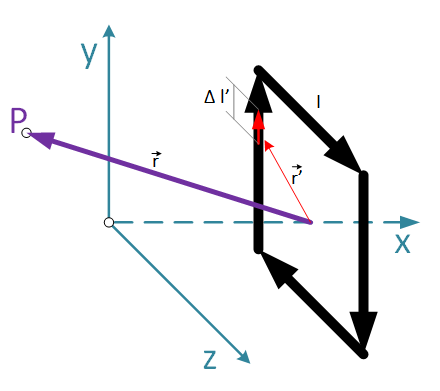

$\vec{B}(\vec{r}) = \frac{N \mu_0}{4\pi}\sum\frac{I'\Delta\vec{l'}\times(\vec{r}-\vec{r'})}{||\vec{r}-\vec{r'}||^3}$ (1.5)

A numerical aproximation for the equation (1.5) it is implemented using the file called:

### 1.2. Magnetic Coils Simulation

To perform simulations for the IS501NMTB, the geometrical parameters for each coil was taken of [1] and are listed below:

mu_0 = 4*pi*1e-7;                 %Magnetic Permeability of Vacuum

**For Z axis**

IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2;
IS501NMTB.Z.h = 0.5 ;
IS501NMTB.Z.N = 20;
IS501NMTB.Z.R = 10.32;
IS501NMTB.Z.Lz = IS501NMTB.Z.N^2*(2^(1/2)*mu_0*IS501NMTB.Z.L^2)/(IS501NMTB.Z.a*pi);
IS501NMTB.Z.tau = IS501NMTB.Z.Lz/IS501NMTB.Z.R;

**For Y axis**

IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2;
IS501NMTB.Y.h = 0.5;
IS501NMTB.Y.N = 35;
IS501NMTB.Y.R = 7.61;
IS501NMTB.Y.Ly = IS501NMTB.Y.N^2*(2^(1/2)*mu_0*IS501NMTB.Y.L^2)/(IS501NMTB.Y.a*pi);
IS501NMTB.Y.tau = IS501NMTB.Y.Ly/IS501NMTB.Y.R;

**For X axis**

IS501NMTB.X.L = 1.03;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
IS501NMTB.X.h = 0.5;
IS501NMTB.X.N = 36;
IS501NMTB.X.R = 14.84;
IS501NMTB.X.Lx = IS501NMTB.X.N^2*(2^(1/2)*mu_0*IS501NMTB.X.L^2)/(IS501NMTB.X.a*pi);
IS501NMTB.X.tau = IS501NMTB.X.Lx/IS501NMTB.X.R;

#### **1.2.1. Simulation for coils**

First, we will simulate the magnetic field generated by the Z coil, Y coil and X coil independently (one coil turn on) over the XY, XZ, and YZ plane with a current of 1A with the following code.

%%%Script to simulate the helmholtz coils
helmholtzSim

Error using load
Unable to find file or directory '1dSimulateData2.mat'.

%%%Get results from previous simulations
%load('1dSimulateData2.mat')

The following figure depicts the simulated distribution of the IS501 NMTB HELMHOLTZ MAGNETIC TEST BED implemented by beihang university.

figure()
h1 = plotHeltholtsCoils(zcoil.spire1,zcoil.spire2,1,2,'b'); hold on;

Unable to resolve the name 'zcoil.spire1'.

h2 = plotHeltholtsCoils(ycoil.spire1,ycoil.spire2,1,2,'k');
h3 = plotHeltholtsCoils(xcoil.spire1,xcoil.spire2,1,2,'g');
legend([h1,h2,h3],'Z-coil','Y-coil','X-coil');
axis equal; xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title('IS501 NMTB HELMHOLTZ MAGNETIC TEST BED');

**Simulation Analisys**

The results for the Z-coil simulation is saved in zcoil variable, the results in the Y-coil simulation is saved in the y coil variable and the results for the X-coil simulation is saved in .

With the following code we will analize which area are almost constant in the midle of the coil with an margin of 0.5% of variance.

tolerance = 0.005; %%%Tolerance of 0.5%

%%% Analize z coils (xy-plane)
max_Bz = max(zcoil.xy.norB, [], 'all');
permitedRangez = [1-tolerance, 1+tolerance] * max_Bz;  
[rowz, colz] = find(zcoil.xy.norB >= permitedRangez(1) & zcoil.xy.norB <= permitedRangez(2));
filteredValuesZ = zcoil.xy.norB(rowz, colz)*1E9;

%%% Analize y coils (xz-plane)
max_By = max(ycoil.xz.norB, [], 'all');
permitedRangey = [1-tolerance, 1+tolerance] * max_By;  
[rowy, coly] = find(ycoil.xz.norB >= permitedRangey(1) & ycoil.xz.norB <= permitedRangey(2));
filteredValuesY = ycoil.xz.norB(rowy, coly)*1E9;

%%% Analize x coils (yz-plane)
max_Bx = max(xcoil.yz.norB, [], 'all');
permitedRangex = [1-tolerance, 1+tolerance] * max_Bx;  
[rowx, colx] = find(xcoil.yz.norB >= permitedRangex(1) & xcoil.yz.norB <= permitedRangex(2));
filteredValuesX = xcoil.yz.norB(rowx, colx)*1E9;

Finally, we generate the figure to see the magnitude of the generated magnetic field

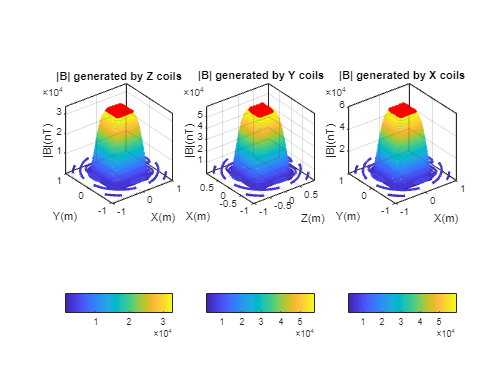

figure()
subplot(1,3,1)
    contour3(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(zcoil.xy.X(rowz, colz),zcoil.xy.Y(rowz, colz),filteredValuesZ,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]);   
    title('|B| generated by Z coils'); axis vis3d; colorbar('southoutside');
subplot(1,3,2)
    contour3(ycoil.xz.Z, ycoil.xz.X,ycoil.xz.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(ycoil.xz.Z(rowy, coly),ycoil.xz.X(rowy, coly),filteredValuesY,'.','Color','r','MarkerSize',11);
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]); 
    title('|B| generated by Y coils');axis vis3d; colorbar('southoutside');
subplot(1,3,3)
    contour3(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.norB*1E9,30,'LineWidth',2); hold on; grid on;
    plot3(xcoil.yz.Y(rowx, colx), xcoil.yz.Z(rowx, colx),filteredValuesX,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('|B|(nT)');
    axis vis3d; %view([0 90]); 
    title('|B| generated by X coils'); axis vis3d; colorbar('southoutside');

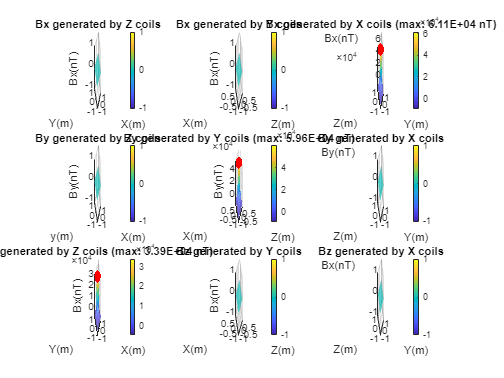

scale = 1E9; %to nT
figure()
subplot(3,3,1)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('Bx(nT)');
    title('Bx generated by Z coils'); colorbar;
subplot(3,3,2)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('Bx(nT)');
    title('Bx generated by Y coils'); colorbar;
subplot(3,3,3)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.Bx*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(xcoil.yz.Y(rowx, colx),xcoil.yz.Z(rowx, colx),filteredValuesX,'.','Color','r','MarkerSize',11);
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('Bx(nT)');
    title(['Bx generated by X coils (max: ', num2str(max_Bx*scale,'%2.2E'), ' nT)']); colorbar;
    
subplot(3,3,4)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('X(m)'); ylabel('y(m)'); zlabel('By(nT)');
    title('By generated by Z coils'); colorbar;
subplot(3,3,5)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(ycoil.xz.Z(rowy, coly), ycoil.xz.X(rowy, coly), filteredValuesY,'.','Color','r','MarkerSize',11);
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('By(nT)');
    title(['By generated by Y coils (max: ', num2str(max_By*scale,'%2.2E'), ' nT)']); colorbar;
subplot(3,3,6)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.By*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('By(nT)');
    title('By generated by X coils'); colorbar;

subplot(3,3,7)
    surf(zcoil.xy.X, zcoil.xy.Y, zcoil.xy.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    plot3(zcoil.xy.X(rowz, colz),zcoil.xy.Y(rowz, colz),filteredValuesZ,'.','Color','r','MarkerSize',11);
    xlabel('X(m)'); ylabel('Y(m)'); zlabel('Bx(nT)');
    title(['Bz generated by Z coils (max: ', num2str(max_Bz*scale,'%2.2E'), ' nT)']); colorbar;
subplot(3,3,8)
    surf(ycoil.xz.Z, ycoil.xz.X, ycoil.xz.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Z(m)'); ylabel('X(m)'); zlabel('Bx(nT)');
    title('Bz generated by Y coils'); colorbar; 
subplot(3,3,9)
    surf(xcoil.yz.Y, xcoil.yz.Z, xcoil.yz.Bz*scale,'EdgeColor','none','FaceAlpha', 0.7);grid on; hold on;
    xlabel('Y(m)'); ylabel('Z(m)'); zlabel('Bx(nT)');
    title('Bz generated by X coils'); colorbar;

Then, we will show the magnetic field in the longitudinal plane generated by coil z, y and x with a current of 1A.

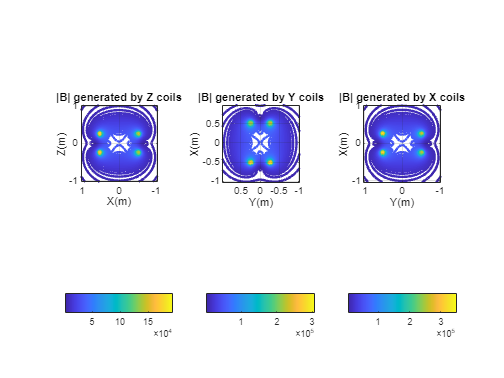

figure()
subplot(1,3,1)
    contour3(zcoil.xz.Z, zcoil.xz.X, zcoil.xz.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('Z(m)'); ylabel('X(m)'); zlabel('B(nT)');
    title('|B| generated by Z coils');axis vis3d;
    view([-90 90]); colorbar('southoutside');
subplot(1,3,2)
    contour3(ycoil.xy.X, ycoil.xy.Y, ycoil.xy.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('B(nT)');
    title('|B| generated by Y coils');axis vis3d; 
    view([-90 90]); colorbar('southoutside')
subplot(1,3,3)
    contour3(xcoil.xy.X, xcoil.xy.Y, xcoil.xy.norB*1E9,100,'LineWidth',2);
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('B(nT)');
    title('|B| generated by X coils');axis vis3d; 
    view([-90 90]); colorbar('southoutside')

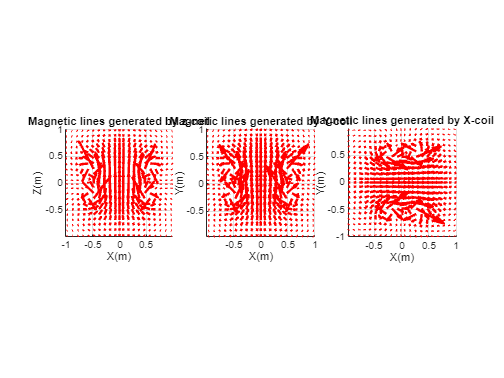

figure    
subplot(1,3,1)
    maxB = max(zcoil.xz.norB(:));
    for i = 1:length(zcoil.xz.X)
        for j = 1:length(zcoil.xz.Z)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([zcoil.xz.X(i,j),0,zcoil.xz.Z(i,j)],[zcoil.xz.Bx(i,j),zcoil.xz.By(i,j),zcoil.xz.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 0]);
    title('Magnetic lines generated by z-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

subplot(1,3,2)
    maxB = max(ycoil.xy.norB(:));
    for i = 1:length(ycoil.xy.X)
        for j = 1:length(ycoil.xy.Y)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([ycoil.xy.X(i,j),ycoil.xy.Y(i,j),0],[ycoil.xy.Bx(i,j),ycoil.xy.By(i,j),ycoil.xy.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 90]);
    title('Magnetic lines generated by Y-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

subplot(1,3,3)
    maxB = max(xcoil.xy.norB(:));
    for i = 1:length(xcoil.xy.X)
        for j = 1:length(xcoil.xy.Y)
            if (mod(i,2)==0)&&(mod(j,2)==0)
                [h1,~] = plotVector([xcoil.xy.X(i,j),xcoil.xy.Y(i,j),0],[xcoil.xy.Bx(i,j),xcoil.xy.By(i,j),xcoil.xy.Bz(i,j)]/maxB,1 ,'r-',' ','m');hold on;
                set(h1,'LineWidth',2,'MaxHeadSize',2);
            end
        end
    end
    view([0 90]);
    title('Magnetic lines generated by X-coil')
    grid on; xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');axis vis3d;

In this simulation we can see that the generated magnetic field is almost constant over the spin axis and in the X-Y plane with a radius of 20cm. The magnetic field over the $Z-axis$ can be generated by the equation (1.2) . And the value of the magnetic Field in the $Z = 0$, $Y=0$ and $Z=0$ is calculated by equation (1.3). The magnetic field magnitude in the $z-axis$ is simulated and diplayed in the following figure. 

mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

%%% Calculate the Bxyz in zCoil
By0_z = functBxyz0(IS501NMTB.Z.N,1,IS501NMTB.Z.a,IS501NMTB.Z.h);
fprintf('The magnetic field in Z = 0 m is: %E nT',By0_z*1E9);

The magnetic field in Z = 0 m is: 3.363147E+04 nT

%%% Calculate the Bxyz in yCoil
By0_y = functBxyz0(IS501NMTB.Y.N,1,IS501NMTB.Y.a,IS501NMTB.Y.h);
fprintf('The magnetic field in Y = 0 m is: %E nT',By0_y*1E9);

The magnetic field in Y = 0 m is: 5.914820E+04 nT

%%% Calculate the Bxyz in xCoil
By0_x = functBxyz0(IS501NMTB.X.N,1,IS501NMTB.X.a,IS501NMTB.X.h);
fprintf('The magnetic field in X = 0 m is: %E nT',By0_x*1E9);

The magnetic field in X = 0 m is: 6.053664E+04 nT

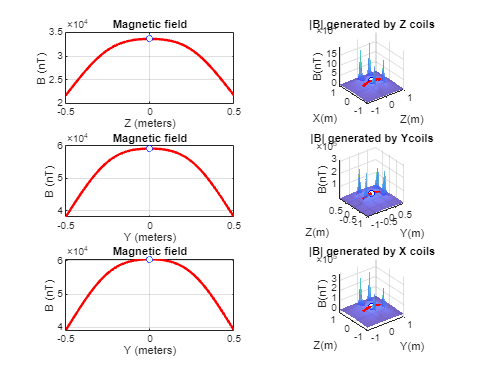

figure()
subplot(3,2,1)
    [Bzz,~,z] = biotSavartPlot(IS501NMTB.Z, 1, length(zcoil.xz.X), 'Z', 'r-'); hold on;
    plot(0,By0_z*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF')
subplot(3,2,2)
     surf(zcoil.xz.Z, zcoil.xz.X, zcoil.xz.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(z,zeros(1,length(zcoil.xz.X)),Bzz*1E9,'r','LineWidth',2);
     plot3(0,0,By0_z*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Z(m)'); ylabel('X(m)'); zlabel('B(nT)');
     title('|B| generated by Z coils');axis vis3d;
    
subplot(3,2,3)
    [Byy,~,y] = biotSavartPlot(IS501NMTB.Y, 1, length(ycoil.xy.X), 'Y', 'r-'); hold on;
    plot(0,By0_y*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF');
subplot(3,2,4)
     surf(ycoil.xy.X, ycoil.xy.Y, ycoil.xy.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(y,zeros(1,length(ycoil.xy.X)),Byy*1E9,'r','LineWidth',2);
     plot3(0,0,By0_y*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Y(m)'); ylabel('Z(m)'); zlabel('B(nT)');
     title('|B| generated by Ycoils');axis vis3d;

subplot(3,2,5)
    [Bxx,~,x] = biotSavartPlot(IS501NMTB.X, 1, length(xcoil.xy.X), 'Y', 'r-'); hold on;
    plot(0,By0_x*1E9,'bo', 'MarkerSize', 5, 'MarkerFaceColor', '#D9FFFF');
subplot(3,2,6)
     surf(xcoil.xy.X, xcoil.xy.Y, xcoil.xy.norB*1E9,'EdgeColor','none','FaceAlpha', 0.7); hold on;
     plot3(x,zeros(1,length(xcoil.xy.X)),Bxx*1E9,'r','LineWidth',2);
     plot3(0,0,By0_x*1E9,'bo','MarkerSize',5,'MarkerFaceColor','#D9FFFF');
     grid on; xlabel('Y(m)'); ylabel('Z(m)'); zlabel('B(nT)');
     title('|B| generated by X coils');axis vis3d;

The magnetic field generated from a Helmholtz Pair is uniform over a relatively large region of space; This space is considered spherical whose center is at the midpoint of the segment that joins the centers of the coils, and the radius measurement is of the order of half the radius of the coils [5]. The above simulations are according with this affirmation due to the generated magnetic field generated at the center of the magnetic chamber are homogeneous within a radius of 20 cm and.

clearvars -except IS501NMTB xcoil ycoil zcoil

function h1 = plotHeltholtsCoils(spire1, spire2, L, width, color)
    % Function to plot two 3D coils (spires) with directional arrows indicating current flow
    % Inputs:
    %   spire1, spire2 - Structures representing each coil with 3D coordinates of segments
    %   L - Scale factor for the direction arrows
    %   width - Line width for the coil plots
    %   color - Color for the coil lines
    
    % Combine the two spires (coils) into a cell array for simplified processing
    spires = {spire1, spire2};
    
    % Loop through each coil (spire) in the cell array
    for s = 1:length(spires)
        % Retrieve all field names from the current coil structure
        fieldsName = fields(spires{s});
        
        % Loop through each segment (field) of the coil
        for i = 1:numel(fieldsName)
            % Calculate the scale for the directional arrow
            % Scale based on the length of the segment and the provided factor L
            scale = (L / 4) / norm((spires{s}.(fieldsName{i})(:,2) - spires{s}.(fieldsName{i})(:,1)));
            
            % Plot the segment of the coil in 3D space
            h1 = plot3(spires{s}.(fieldsName{i})(1,:), spires{s}.(fieldsName{i})(2,:), spires{s}.(fieldsName{i})(3,:)); 
            hold on; % Retain the plot for additional plotting
            
            % Set the appearance of the segment line
            set(h1, 'LineWidth', width, 'Color', color);
            
            % Plot the direction of the current as a scaled vector (arrow)
            % Uses plotVector to add a directional arrow from start to end of the segment
            [h2, ~] = plotVector(spires{s}.(fieldsName{i})(:,1), ...
                                (spires{s}.(fieldsName{i})(:,2) - spires{s}.(fieldsName{i})(:,1)) * scale, ...
                                1, 'r--', ' ', 'e'); % Red dashed arrow
                                
            % Set appearance of the directional arrow
            set(h2, 'LineWidth', width + 1, 'MaxHeadSize', 2);
        end
    end
end


function [B,h1,z] = biotSavartPlot(IS501NMTBAxis, I, longited, label, style)
    % Given Parameters
    mu_0 = 4*pi*1e-7;    % Permeability in the vacum
    N = IS501NMTBAxis.N; % Number of coils
    a = IS501NMTBAxis.a; % Solenoid (meters)
    h = IS501NMTBAxis.h; % Distance between solenoids (meters)
    z = linspace(-h, h, longited);     % Values of the axis
    
    % B(x) calculus
    B = ((2 * mu_0 * N* I * a^2)/pi) * (1 ./ ((a^2 + (z + h/2).^2) .* (2*a^2 + (z + h/2).^2).^(1/2)) + ...
                                     1 ./ ((a^2 + (z - h/2).^2) .* (2*a^2 + (z - h/2).^2).^(1/2)));
    
    % Plot B(z)
    h1 = plot(z, B*1E9, style, 'LineWidth', 2);
    xlabel([label,' (meters)']);
    ylabel('B (nT)');
    title('Magnetic field');
    grid on;
end

## **Bibliography**

[1]Uscategui, Jhonny, et al. "High-Precision Magnetic Testbed Design and Simulation for LEO Small-Satellite Control Test." *Aerospace* 10.7 (2023): 640.

[2]Chaisakulsurin, Jormpon, et al. "Hardware-in-the-Loop Simulation Testbed for Three-Axis Earth's Magnetic Field Generation Based on 2.4-Meter Square Helmholtz Coils." *2023 IEEE/ION Position, Location and Navigation Symposium (PLANS)*. IEEE, 2023.

[3]Al-Abri, Aaisha Rashid, et al. "Helmholtz cage for attitude testing of cubesat." *2022 Advances in Science and Engineering Technology International Conferences (ASET)*. IEEE, 2022.

[4] Restrepo, Andrés F., Edinson Franco, and Carlos R. Pinedo. "Metodología de diseño e implementación de un sistema para generación de campos magnéticos uniformes con bobinas Helmholtz Cuadrada Tri-Axial." *Información tecnológica* 25.2 (2014): 03-14.

[5]Martínez, E. "Bobinas de Helmholtz." *Mexico, México DF* (2015).

[6] [Espira Cuadrada Ley de Biot-Savart I - YouTube](https://www.youtube.com/watch?v=IvfkEk6_vks&ab_channel=Dem%C3%B3critoPit%C3%A1goras)

[7]Lapucci, Tommaso, et al. "Soft and Hard Iron Compensation for the Compasses of an Operational Towed Hydrophone Array without Sensor Motion by a Helmholtz Coil." *Sensors* 21.23 (2021): 8104.

[8][Magnetometer Calibration - MATLAB & Simulink - MathWorks América Latina](https://la.mathworks.com/help/nav/ug/magnetometer-calibration.html?s_tid=srchtitle_site_search_1_magnetometer%20calibration)